**An Introduction to Robotics, By Prof. Hamid D. Taghirad & Mohammad A. Khosravi Copyright ARAS @2023**

# This code provides Optimal solution of redundancy problem with Singularity Circumvention objective in 3R robot

## Parameter Definitions

clear all
global Par

optimization options

options = optimoptions(@fmincon,'Display','off'); % Turn off Display


initial conditions and parameter settings

Par.q0=pi/180*[-180;-179;10];  % Initial joint angles [theta1; theta2; theta3] in radians
Par.qdot0=[0;0;0];  % Initial joint velocities [theta1_dot; theta2_dot; theta3_dot]
Par.a=[1;1;0.3];  % Link lengths [a1; a2; a3]
Par.t=[0.01;1];  % Time step (dt) and total time (t_final) for trajectory generation
Par.qd=pi/180*[60;-80;-10];  % Desired final joint angles in radians for obstacle avoidance

Par.qmin=pi/180*[-190;-190;-30]; Par.qdotmin=-Inf*[1;1;1];  % Joint variable lower bound
Par.qmax=pi/180*[-170;-170;30]; Par.qdotmax=+Inf*[1;1;1];  % Joint variable upper bound

Par.selection = 'ka';  % Selection of optimization cost function
                         % Use 'mu' for manipulability measure
                         % Use 'ka' for manipulability measure
                         % Use 'ba' for base solution


Problem initialization

q0=Par.q0;qdot0=Par.qdot0;
th1=q0(1);th2=q0(2);th3=q0(3);
th12=th1+th2;th123=th12+th3;
s1=sin(th1);c1=cos(th1);
s12=sin(th12);c12=cos(th12);
s123=sin(th123);c123=cos(th123);
a1=Par.a(1);a2=Par.a(2);a3=Par.a(3);


Forward Kinematics for the first point

x0=a1*c1+a2*c12+a3*c123;
y0=a1*s1+a2*s12+a3*s123;

## Trajectory Generation

dt=Par.t(1); tfinal=Par.t(2);
t=0:dt:tfinal; t=t';
n=max(size(t));dt=t(2)-t(1);

Path generation

x=x0+0*t;  % x-coordinate trajectory
y=y0-(3-2*t).*t.^2*(y0+0.1);  % y-coordinate trajectory
xdot=0*t;  % x-coordinate velocity
ydot=(y0+0.1)*(6*t.^2-6*t);  % y-coordinate velocity
z(:,1)=[q0;qdot0];  % Initialize the variable z to store the joint angles and velocities

## Optimization scheme

for i=1:n
    chi=[x(i);y(i)];chidot=[xdot(i);ydot(i)];
    Par.chi=chi; Par.chidot=chidot;  % Pass the desired position and velocity to the constraint function
    th1=z(1,i);th2=z(2,i);th3=z(3,i);
    th12=th1+th2;th123=th12+th3;
    s1=sin(th1);c1=cos(th1);
    s12=sin(th12);c12=cos(th12);
    s123=sin(th123);c123=cos(th123);
    J=[-a1*s1-a2*s12-a3*s123    -a2*s12-a3*s123  -a3*s123;
            a1*c1+a2*c12+a3*c123     a2*c12+a3*c123   a3*c123];
     Lb=[Par.qmin;Par.qdotmin];
     Ub=[Par.qmax;Par.qdotmax];
    nonlcon=@kinematics;
    % Use fmincon to find the optimal joint angles and velocities for each time step
    [sol(:,i),fval(i),eflag(i),output(:,i)]=fmincon(@sing_avoid, z(:,i),[],[],[],[],Lb,Ub, nonlcon,options);
    z(:,i+1)=sol(:,i);  % Store the optimized values for the next time step
end 

## Output generation

z=z(:,1:n);  % Eliminate the last iteration from output

th1=z(1,:);th2=z(2,:);th3=z(3,:);
th12=th1+th2;th123=th12+th3;
s1=sin(th1);c1=cos(th1);
s12=sin(th12);c12=cos(th12);
s123=sin(th123);c123=cos(th123);

Forward Kinematics for the solution

px0=0*c1; py0=0*s1;
px1=a1*c1; py1=a1*s1;
px2=a1*c1+a2*c12; py2=a1*s1+a2*s12;
px3=a1*c1+a2*c12+a3*c123; py3=a1*s1+a2*s12+a3*s123;
px0=px0';px1=px1';px2=px2';px3=px3';
py0=py0';py1=py1';py2=py2';py3=py3';

xrobot=[px0 px1 px2 px3]; yrobot=[py0 py1 py2 py3];

## Robot position plot

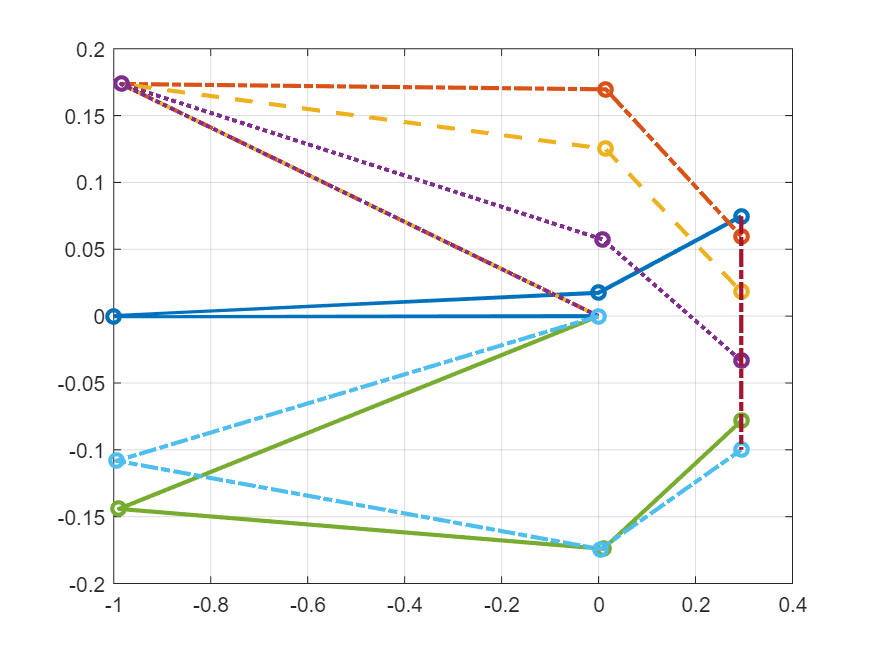

figure(2),
plot(xrobot(1,:),yrobot(1,:),'-o',...
        xrobot(0.2*(i-1),:),yrobot(0.2*(i-1),:),'-.o',...
        xrobot(0.4*(i-1),:),yrobot(0.4*(i-1),:),'--o',...
        xrobot(0.6*(i-1),:),yrobot(0.6*(i-1),:),':o',...
        xrobot(0.8*(i-1),:),yrobot(0.8*(i-1),:),'-o',...
        xrobot(i,:),yrobot(i,:),'-.o',...
        px3,py3,'-.');  % Plot the robot trajectory and final position
grid
set(findall(figure(2),'type','line'),'linewidth',2)

## Optimization Cost function

% Nested function that defines the cost function to be minimized during optimization

function V=sing_avoid(z)
    global Par
    q=z(1:3); qdot=z(4:6);
    a1=Par.a(1);a2=Par.a(2);a3=Par.a(3);
    th1=z(1);th2=z(2);th3=z(3);
    th12=th1+th2;th123=th12+th3;
    s1=sin(th1);c1=cos(th1);
    s12=sin(th12);c12=cos(th12);
    s123=sin(th123);c123=cos(th123);
    J=[-a1*s1-a2*s12    -a2*s12
         a1*c1+a2*c12     a2*c12];
    if Par.selection == 'mu';
        V=-det(J*J')^0.5;  % Manipulability measure
    elseif Par.selection == 'ka';
        V=-rcond(J);  % Dexterity measure
    else
        V=norm(z,2)^2;
    end 
end     % end of nested function



Optimization Constraint function

 Nested function that defines the kinematic constraints for optimization

function [c,ceq]=kinematics(z)
    global Par
    a1=Par.a(1);a2=Par.a(2);a3=Par.a(3);
    th1=z(1);th2=z(2);th3=z(3);
    th12=th1+th2;th123=th12+th3;
    s1=sin(th1);c1=cos(th1);
    s12=sin(th12);c12=cos(th12);
    s123=sin(th123);c123=cos(th123);
    J=[-a1*s1-a2*s12-a3*s123    -a2*s12-a3*s123  -a3*s123;
            a1*c1+a2*c12+a3*c123     a2*c12+a3*c123   a3*c123];
    x=[a1*c1+a2*c12+a3*c123;  a1*s1+a2*s12+a3*s123];  % Kinematics
    % Kinematics and Jacobian constraints
    ceq=[Par.chi-x;Par.chidot-J*z(4:6)];  
    % No inequality constraint
    c=[];
end  % end of nested function
